# Series de fourier

## Visualizar exponenciales complejas

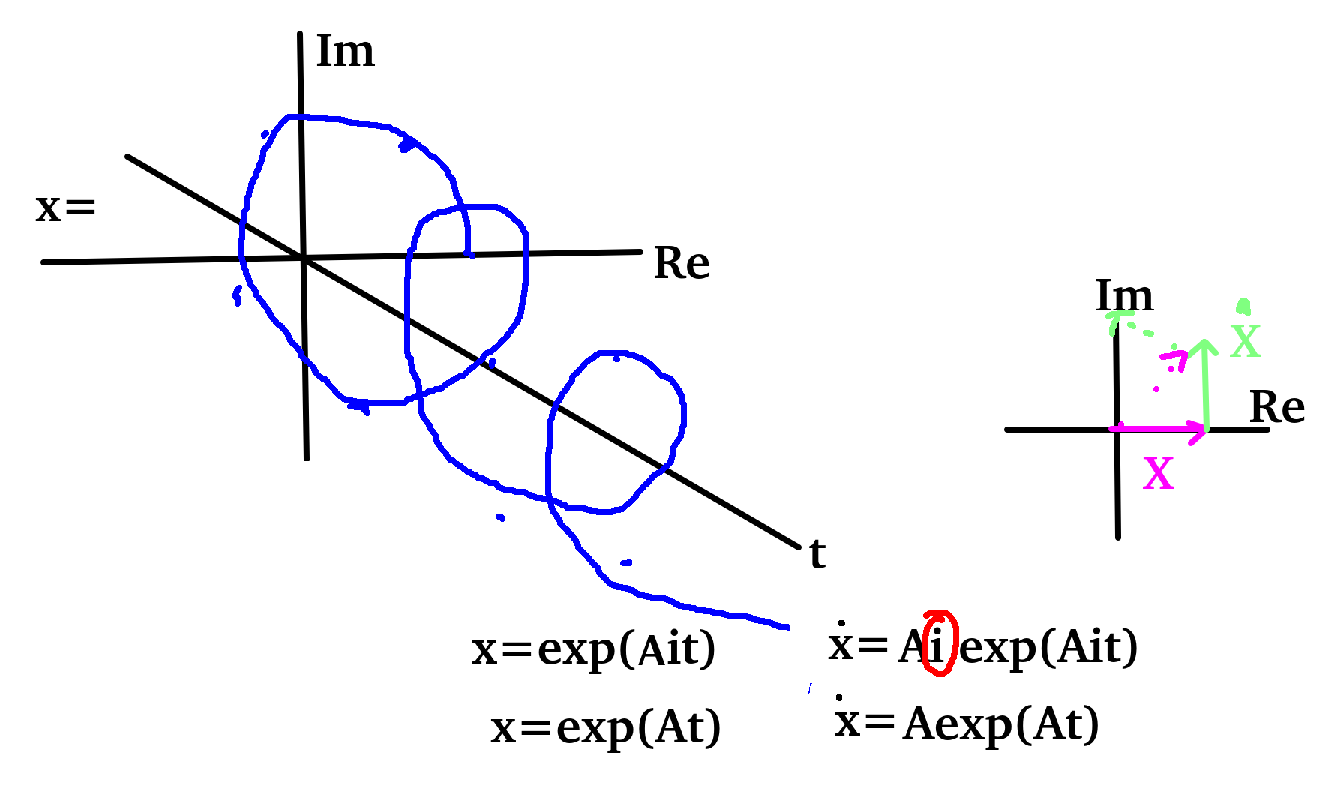

syms t
A=1;
x=exp(1i*t*A)

$$x = {\mathrm{e}}^{t\,\mathrm{i}}$$


x_Re=real(x)

$$x\_Re = \mathrm{real}\left({\mathrm{e}}^{t\,\mathrm{i}}\right)$$

x_Im=imag(x)

$$x\_Im = \mathrm{imag}\left({\mathrm{e}}^{t\,\mathrm{i}}\right)$$

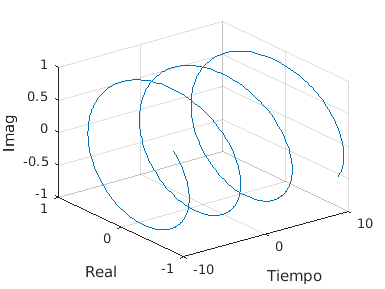


fplot3(t,x_Re,x_Im,[-10  10])
ylabel("Real")
zlabel("Imag")
xlabel("Tiempo")

Exponencial compleja

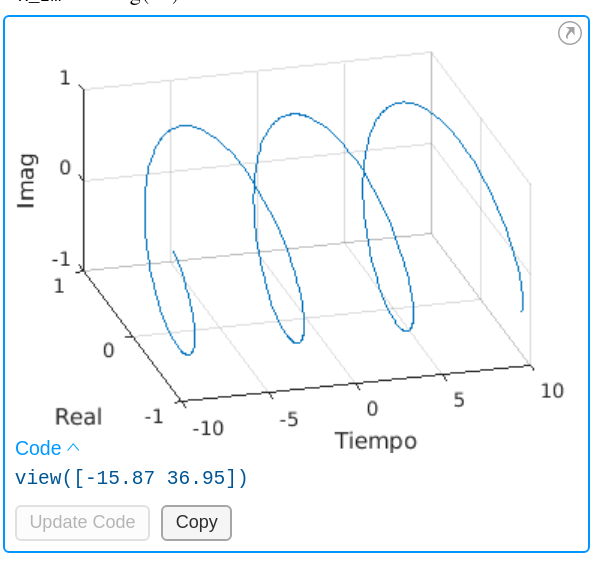

La parte imaginaria se parece a: Seno

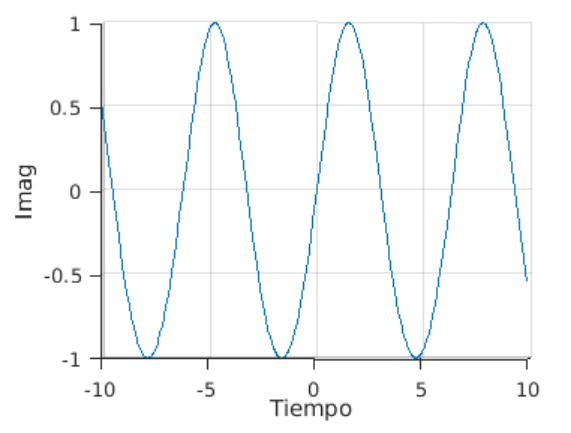

La parte real se parece a: Coseno

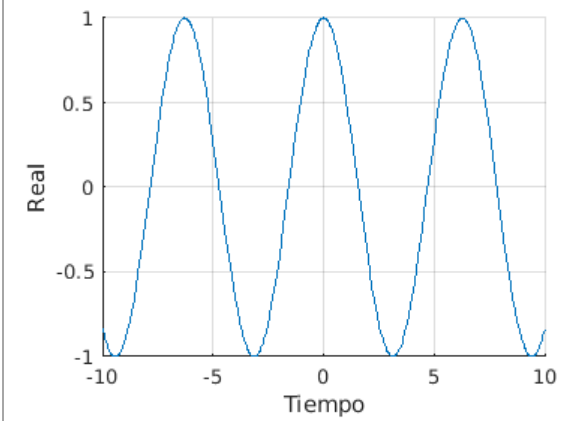

Calcular la parte real ($cos(t)$) e imaginaria $sin(t)$ de la función:


$$x=e^{Ait}$$


Usar las fórmulas para calcular la parte real e imaginaria de un número complejo.

x_1=exp(1i*t)

$$x\_1 = {\mathrm{e}}^{t\,\mathrm{i}}$$

x_2=exp(-1i*t)

$$x\_2 = {\mathrm{e}}^{-t\,\mathrm{i}}$$

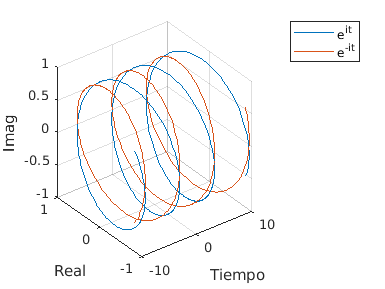


x_Re=real(x_1);
x_Im=imag(x_1);

figure
fplot3(t,x_Re,x_Im,[-10  10])
hold on

x_Re=real(x_2);
x_Im=imag(x_2);

fplot3(t,x_Re,x_Im,[-10  10])
hold off

ylabel("Real")
zlabel("Imag")
xlabel("Tiempo")
legend("e^{it}","e^{-it}")

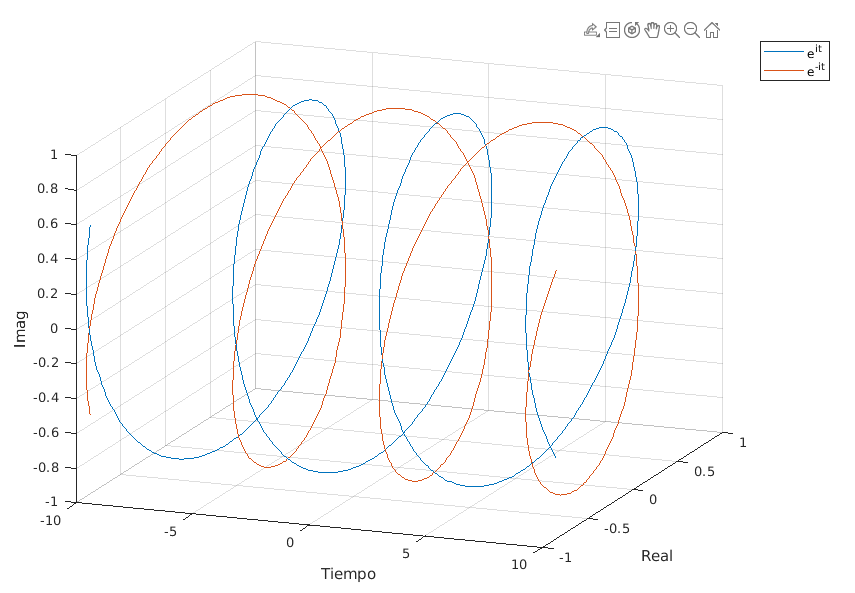

Frecuencia positiva: Contrario a las manecillas del reloj

Frecuencia negativa: Sentido de las manecillas del reloj

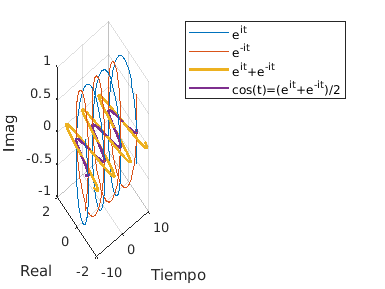

x_Re=real(x_1);
x_Im=imag(x_1);

figure
fplot3(t,x_Re,x_Im,[-10  10])
hold on

x_Re=real(x_2);
x_Im=imag(x_2);

fplot3(t,x_Re,x_Im,[-10  10])

x_Re=real(x_1);
x_Im=imag(x_1);
fplot(t,x_1+x_2,[-10  10],'LineWidth',2)
fplot(t,(x_1+x_2)/2,[-10  10],'LineWidth',2)
hold off

ylabel("Real")
zlabel("Imag")
xlabel("Tiempo")
legend("e^{it}","e^{-it}","e^{it}+e^{-it}","cos(t)=(e^{it}+e^{-it})/2 ")